# Data Valid Example Testbench

Run this test bench to simulate the `data_valid_example` model, and compare the Simulink output to a MATLAB reference.

#### Define filter coefficients and inputs

h = fdesign.lowpass('n,fp,fst', 21, 0.45, 0.55);
Hd = design(h, 'equiripple', 'StopbandShape', 'flat');

filter_coeff = Hd.Numerator;
filter_input = repmat(chirp(0:299,0,299,0.4),1,2);

filter_coeff = fi(filter_coeff,1,18);
filter_input = fi(filter_input,1,18);

ref_out = filter(filter_coeff,1,filter_input);

#### Simulate model and verify results against reference

Insert random number of gaps (up to `max_gap`) to the filter input in order to verify the data valid interface.

max_gap = 2; 
slout = sim('data_valid_example');

Process logged outputs from the simulation. Invalid output data (when output valid == false) are removed.

logged_data = slout.logsout.getElement('output data').Values.data;
logged_valid = slout.logsout.getElement('output valid').Values.data;

sim_out = logged_data(logged_valid);
sim_out = transpose(sim_out);

Compare to MATLAB reference and plot results.

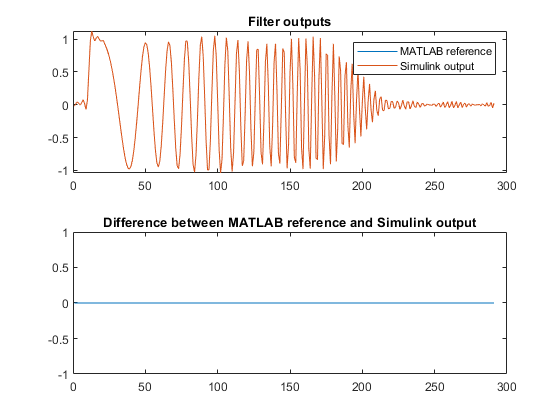

idx = 1:min(length(ref_out),length(sim_out));
err = double(ref_out(idx))-sim_out(idx);

tiledlayout('flow')
nexttile; plot(idx,ref_out(idx), idx,sim_out(idx))
title('Filter outputs'); legend('MATLAB reference','Simulink output')
nexttile; plot(idx,err)
title('Difference between MATLAB reference and Simulink output')